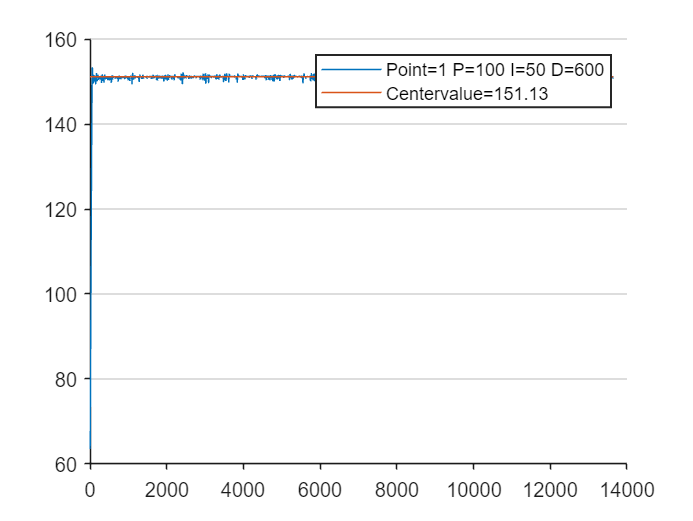

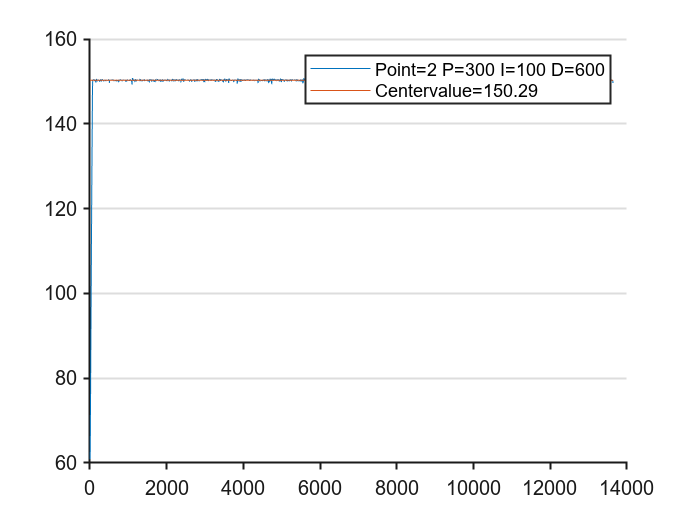

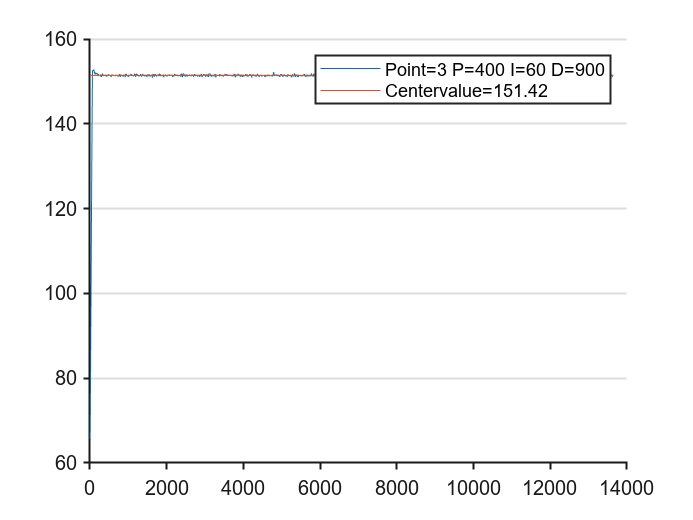

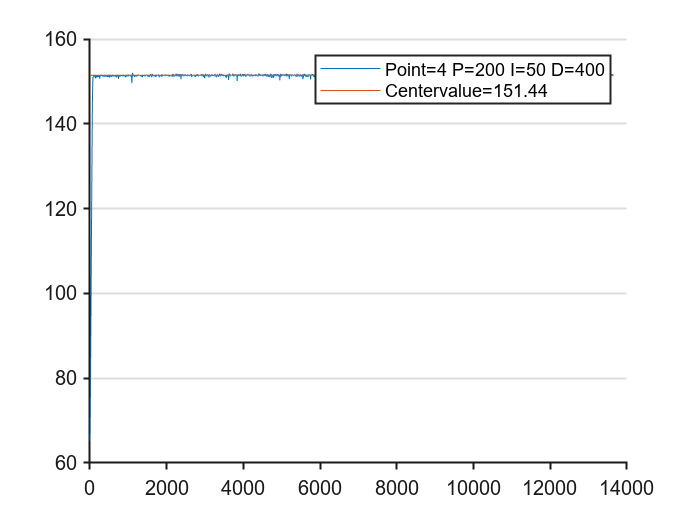

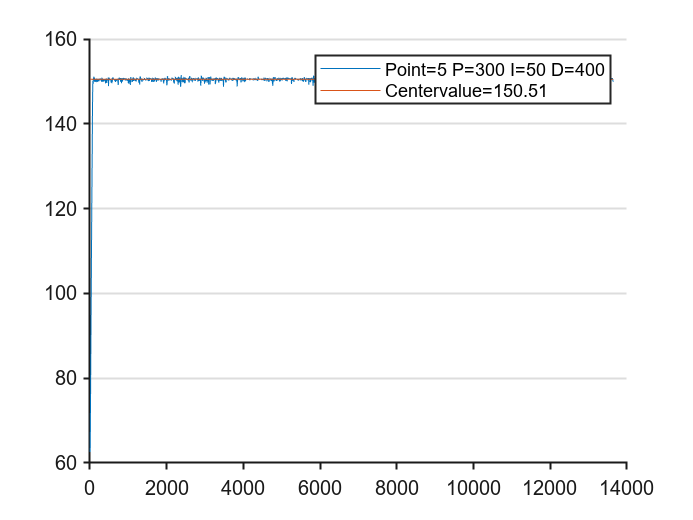

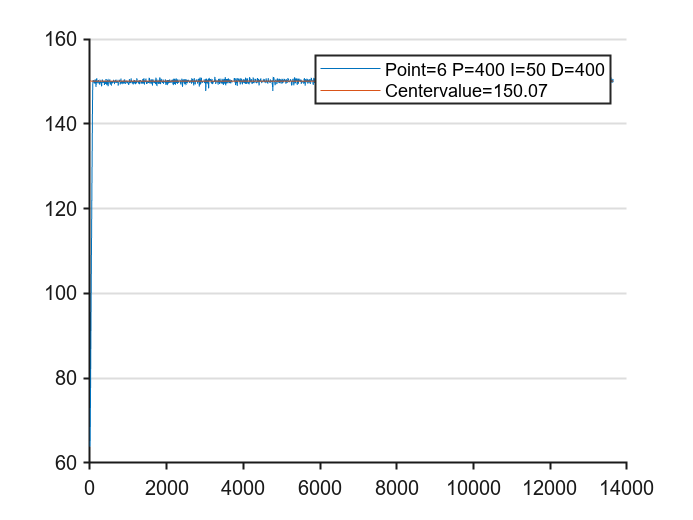

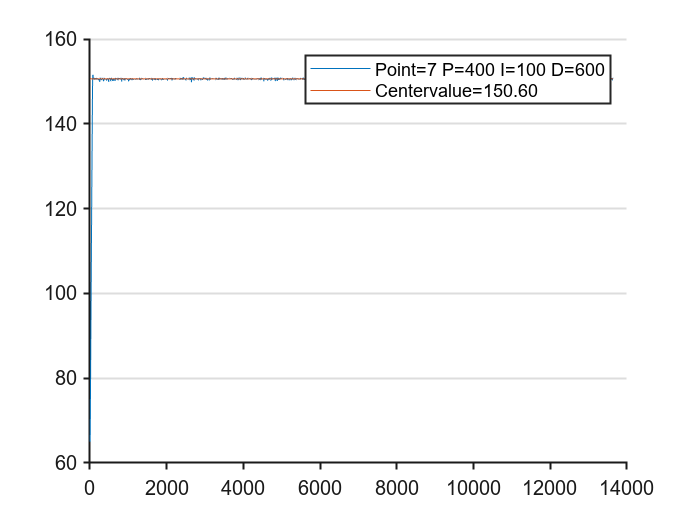

% 单个文件读取后的图表绘制
% 大致逻辑：读取文件名获取基本信息（当前设定温度，七个点的 PID 值）
% 读取文件内数据，分别绘制每个点的曲线图，最后绘制一张七个点的曲线图，各图包含示例，调整曲线图样式。
clear;
filepath = "Compare\temp1502_100_50_600_300_100_600_400_60_900_200_50_400_300_50_400_400_50_400_400_100_600_0.333s_2000.txt";
[filepath,name,ext] = fileparts(filepath);
str = strsplit(name,'_');
parastr(7,3) = string(0);
% 得到七个点的 P、I、D 参数值
for p_i = 1:7
    for p_j = 3:-1:1
        parastr(p_i,(4 - p_j)) = str(p_i*3 - p_j + 2);
    end
end

% 预准备表头名称
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};

% 读取表格数据，表头名称赋值
DATA = readtable("Compare\temp1502_100_50_600_300_100_600_400_60_900_200_50_400_300_50_400_400_50_400_400_100_600_0.333s_2000.txt");
DATA.Properties.VariableNames = TableColumnNames;
% arraydata(height(DATA),7) = (0);

% 根据数据获取 X 轴长度
X = linspace(1,height(DATA),height(DATA));

% 计算稳态的实际中心温度值
SSData = DATA(500:end,:);
CenterValue = [0,0,0,0,0,0,0];
for i = 1:1:7
    CenterValue(i) = ...
    sum(table2array(SSData(:,i)) - table2array(SSData(:,i+7)))...
    /height(SSData) + 150;
end

% 绘制各个点曲线图
for f_i = 1:1:7
    figure;
    plot(X,table2array(DATA(:,f_i)), ...
        'DisplayName',sprintf("Point=%d P=%s I=%s D=%s",f_i,parastr(f_i,1),parastr(f_i,2),parastr(f_i,3)));
    hold on;
    plot(X,repmat(CenterValue(f_i),height(DATA),1), ...
        'DisplayName',sprintf("Centervalue=%.2f",CenterValue(f_i)));
    set(gca,'Box','off', ...                                    % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    hold off;
    legend;
end

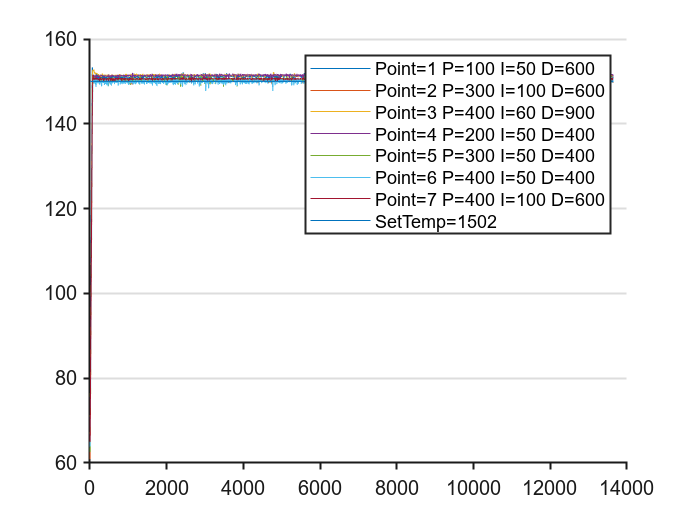


% 绘制七个点的总曲线图
    figure;
for tf_i = 1:1:7
    plot(X,table2array(DATA(:,tf_i)), ...
        'DisplayName',sprintf("Point=%d P=%s I=%s D=%s",tf_i,parastr(tf_i,1),parastr(tf_i,2),parastr(tf_i,3)));
    hold on;
end
plot(X,table2array(DATA(:,8)), ...
    'DisplayName',sprintf("SetTemp=%s",extractAfter(str(1),"temp")));
set( gca,'Box','off', ...                               % 边框开关
    'LineWidth',1, ...                                  % 线宽（非数据线）
    'XGrid','off','YGrid','on', ...                     % 网格开关
    'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
    'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
hold off;
legend;